function garfieldMask=detect_garfield(strip, garfieldColour)

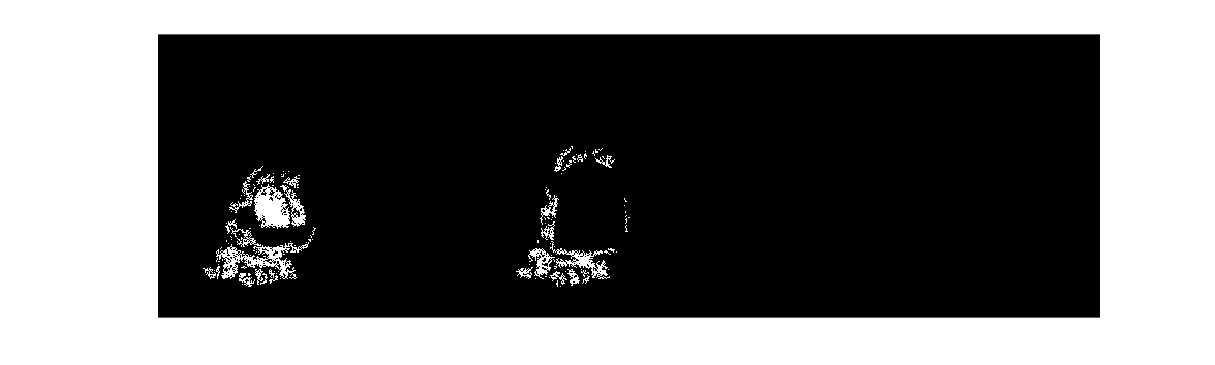

% function garfieldMask=detect_garfield(stripImage, garfieldColour)

% Find minimum and maximum bounds of Garfield colours
[sv,lv]=bounds(garfieldColour);

% Set minimum and maximum limits on Garfield's colour
garfieldColourMin=permute(double(sv),[3 1 2]);
garfieldColourMax=permute(double(lv),[3 1 2]);

% Create a mask for each colour
garfieldMask=and(rotatedImages{imageNumber}>=garfieldColourMin...
    ,rotatedImages{imageNumber}<=garfieldColourMax);

% Combine the mask into one logical mask
garfieldMask=logical(prod(garfieldMask,3));

image_show_resize(garfieldMask);

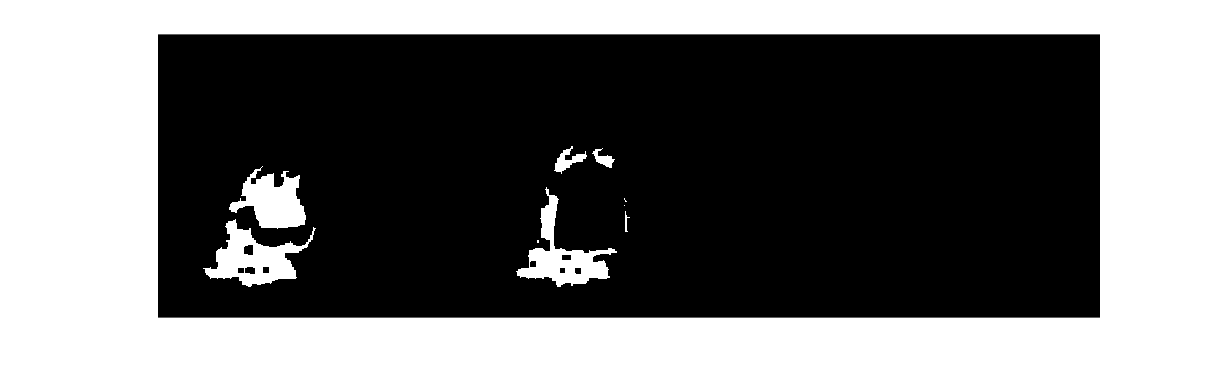


% Clean up stray false detections
garfieldMask = imclose(garfieldMask,strel('disk',3));

image_show_resize(garfieldMask);

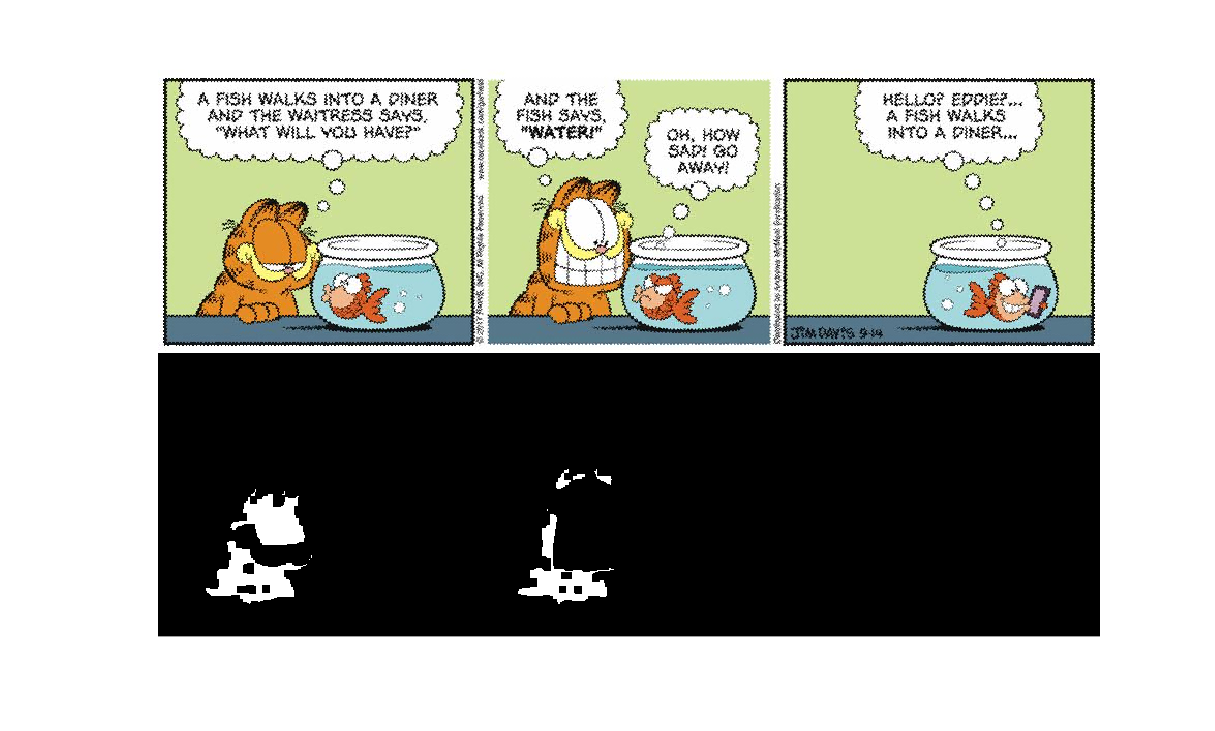


garfieldMask = imerode(garfieldMask,strel('square',3));

image_show_resize(imtile({rotatedImages{imageNumber},garfieldMask}));


% end